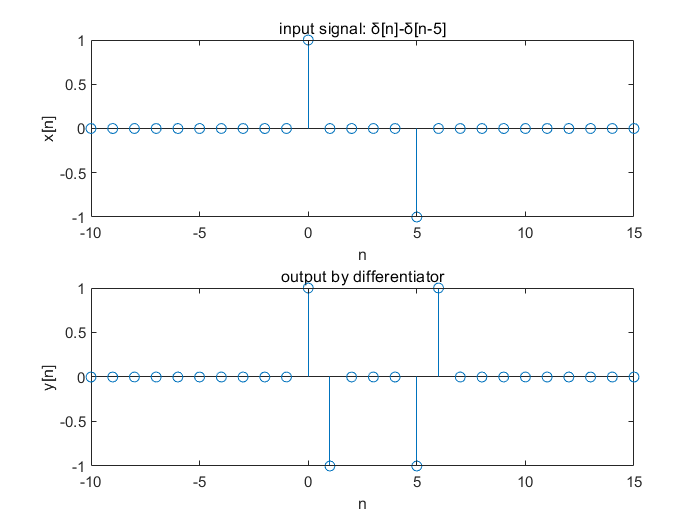


clc;
clear;
close all;
n=-10:20;
delta_n=(n==0);
delta_n5=(n==5);
y1=delta_n-delta_n5;
y1_differ=differ(y1);
y1_integ=integ(y1);

figure
subplot(2,1,1)
stem(n,y1),xlabel('n'),ylabel('x[n]'),title('input signal: δ[n]-δ[n-5]'),xlim([-10,15])
subplot(2,1,2)
stem(n,y1_differ),xlabel('n'),ylabel('y[n]'),title('output by differentiator'),xlim([-10,15])

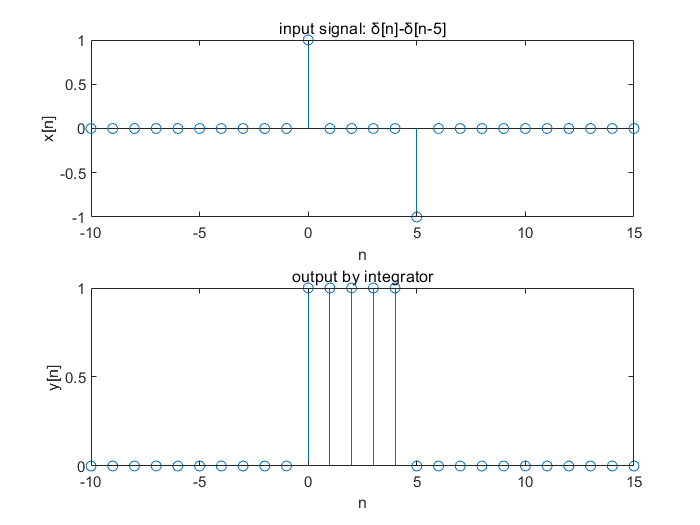

figure
subplot(2,1,1)
stem(n,y1),xlabel('n'),ylabel('x[n]'),title('input signal: δ[n]-δ[n-5]'),xlim([-10,15])
subplot(2,1,2)
stem(n,y1_integ),xlabel('n'),ylabel('y[n]'),title('output by integrator'),xlim([-10,15])

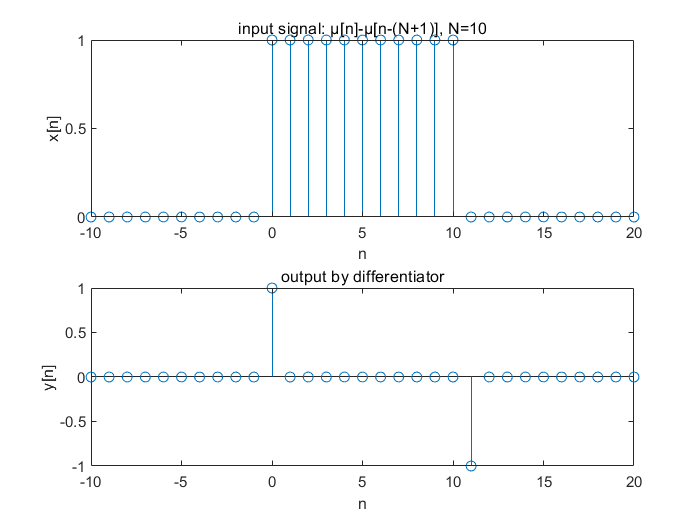


miu_n=(n>=0);
miu_n11=(n>=11);
y2=miu_n-miu_n11;
y2_differ=differ(y2);
y2_integ=integ(y2);

figure
subplot(2,1,1)
stem(n,y2),xlabel('n'),ylabel('x[n]'),title('input signal: μ[n]-μ[n-(N+1)], N=10');
subplot(2,1,2)
stem(n,y2_differ),xlabel('n'),ylabel('y[n]'),title('output by differentiator');

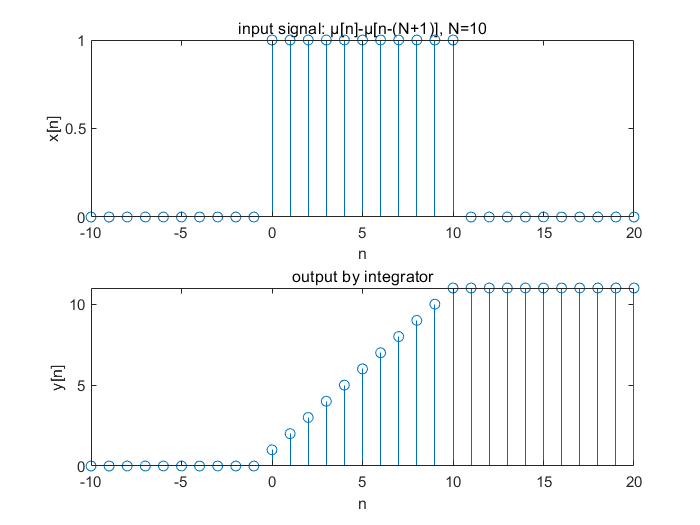

figure
subplot(2,1,1)
stem(n,y2),xlabel('n'),ylabel('x[n]'),title('input signal: μ[n]-μ[n-(N+1)], N=10');
subplot(2,1,2)
stem(n,y2_integ),xlabel('n'),ylabel('y[n]'),title('output by integrator');